# Four Legged Spider Robot Locomotion Using DDPG Agent

This example shows how to train a Four Legged Spider Robot to walk using a deep deterministic policy gradient (DDPG) agent. The robot in this example is modeled using Simscape™ Multibody™. For more information on DDPG agents, see [Deep Deterministic Policy Gradient Agents](docid:rl_ug#mw_3a8116dc-284e-4d85-a31c-0921ec03916e).

#### **Importent Link!   **[**https://www.mathworks.com/help/reinforcement-learning/ug/train-reinforcement-learning-agents.html**](https://www.mathworks.com/help/reinforcement-learning/ug/train-reinforcement-learning-agents.html)

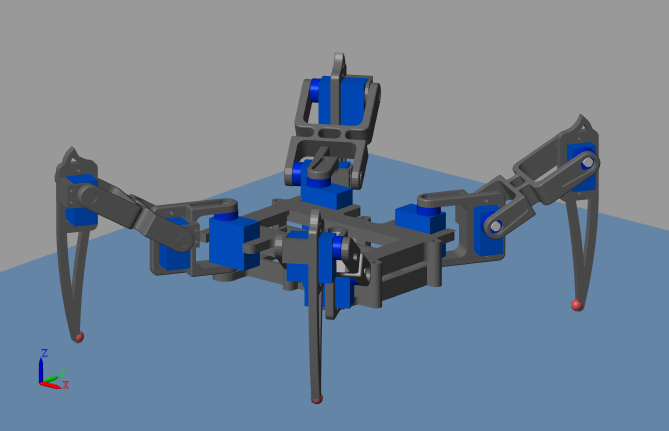

# Robot Training 

Load the necessary parameters into the base workspace in MATLAB®.

SpiderParameters

## Spider Robot Model

The environment for this example is a four-legged 12-joint robot, and the training goal is to make the robot walk **on a ramp **where the robot must overcome a speed bump with a tilting angle of 11 degrees.

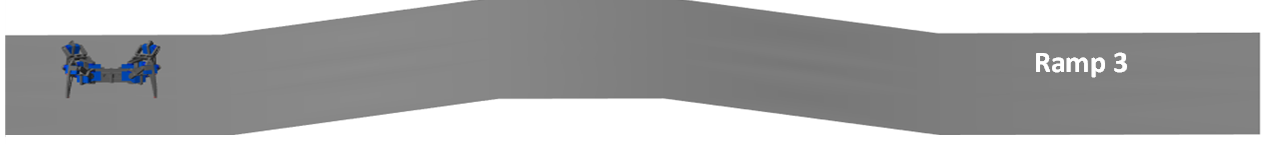

Open the model. 

mdl = 'Ramp3_Model';
open_system(mdl)

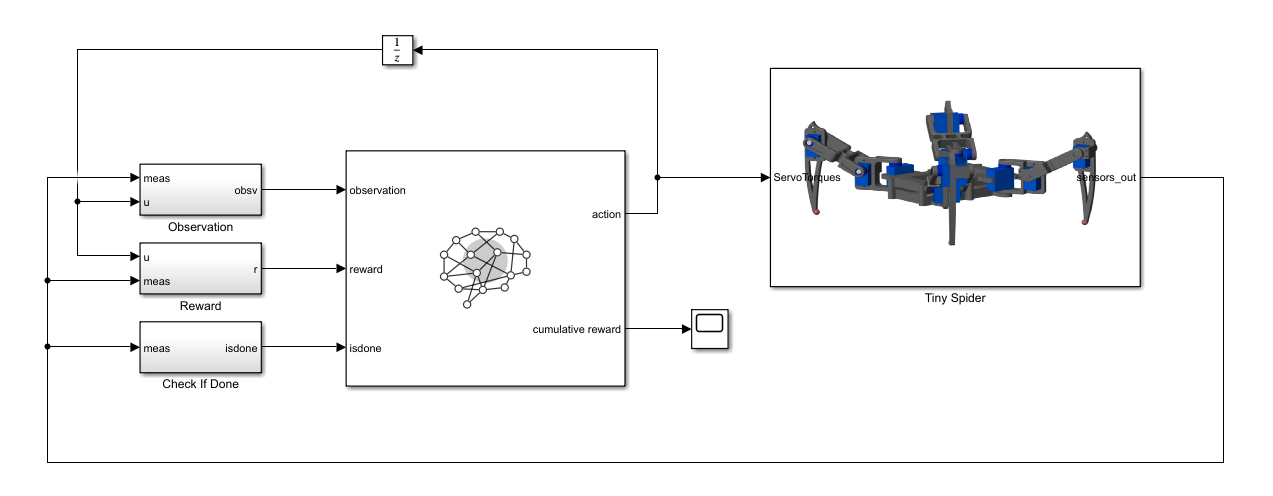

The robot is modeled using Simscape Multibody with its main structural components consisting the environment, which contains the robot model and the physical environment around the robot (Tiny Spider Block), reinforcement learning agent and the required inputs of the agent such like the observations vector, the reward value, and the stopping criteria The robots' joints are actuated by torque signals provided by the RL Agent.

The robot's body consists of two main parts: the lower and upper parts. The lower body is the heaviest part of the robot since it will contain batteries. Moreover, it will be the reference that describes the robot's height, orientation, and speed, where the upper part is a robot cover containing servo motor holders with the robot's four legs attached through the coxa joint. 

The leg model consists three links: Tibia, Femur, and Coxa. The links are connected using three revolute joints: body-coxa that rotates around the z-axis, the coxa-femur joint that rotates around the X axis, and the femur-tibia joint that rotates around the x-axis. All robots' parts  properties such as shape, dimensions, inertia, and the center of mass are calculated from the imported CAD model into the Simscape "File Solid" block.

#### Observations

The robot environment provides 56 observations to the agent, each normalized between –1 and 1. These observations are:

- Z (vertical) position of the body center of mass

- Quaternion representing the orientation of the body

- X (forward), Y (vertical), and Z (lateral) velocities of the body at the center of mass

- Roll, pitch, and yaw rates of the body

- Angular positions and velocities of the body-Coxa , Coxa-Femur and Femur joints for each leg

- Normal and friction force due to ground contact for each leg

- Action values (torque for each joint) from the previous time step

For all four legs, the initial values for body-Coxa, Coxa-Femur, and Femur joints are set based on the inverse kinematics analysis that archives body height of 20 mm and x,y position of each leg tip about its body-coxa joints of 40mm,80mm respectively. 

#### Actions

The agent generates eight actions normalized between –1 and 1. After multiplying with a scaling factor, these correspond to the twelve joint torque signals for the revolute joints. The overall joint torque bounds are +/– 5 N·m for each joint.

#### Reward

The agent receives the reward function at every time step during training. Positive rewards incentivize the agent to execute correct actions, while negative penalties discourage it from doing what is wrong. In this work, implementing the RL agent aims to find a locomotion policy that allows the robot to move forward. The reward function motivates the robot to move forward by providing a positive reward for positive forward velocity ($v_{x}$). It also encourages the agent to avoid early termination by providing a constant reward ( $\lambda_{\Delta t} \frac{Ts}{Tf}$ ) at each time step. The remaining terms in the reward function are penalties that discourage the actor from searching in undesirable states. The term ( $p_{z_{body}}- p_{z_{body,dh}}$) is the difference between the instant robot height and the desired height, and it is squared to keep the value positive, this will punch the agent for deviations from the target height. The last term$\lambda_{u} \sum_{i,l}(u_{t-1}^{i,l})^2$  is the summation of the squared joints torques, and it represents a penalty of using excessive joint torques which will minimize the total actuators effort.


$$r_{t}=\lambda_{v_{x}} v_{x}+ \lambda_{\Delta t}  \frac{Ts}{Tf}- \lambda_{z}  (p_{z_{body}}- p_{z_{body,dh}} )^2  -\lambda_{u} \sum_{i,l}(u_{t-1}^{i,l})^2 $$


#### Episode Termination

During training or simulation, the episode terminates if any of the following situations occur.

- The height of the body's center of gravity from the ground is below a certain, which means the robot has fallen, 

- The roll, pitch or yaw angles are outside bounds, and the robot could have fallen or rolled over. 

## Create Environment Interface

Specify the parameters for the observation set.

numObs = 56;
obsInfo = rlNumericSpec([numObs 1]);
obsInfo.Name = 'observations';

Specify the parameters for the action set.

numAct = 12;
actInfo = rlNumericSpec([numAct 1],'LowerLimit',-1,'UpperLimit', 1);
actInfo.Name = 'torque';

 Create the environment using the reinforcement learning model.

blk = [mdl, '/RL Agent'];
env = rlSimulinkEnv(mdl,blk,obsInfo,actInfo);

During training, the reset function introduces random deviations into the initial joint angles and angular velocities.

env.ResetFcn = @SpiderResetFcn2;

## Create DDPG agent

The DDPG agent approximates the long-term reward given observations and actions by using a critic value function representation. The agent also decides which action to take given the observations, using an actor representation. The actor and critic networks for this example are inspired by [2].

For more information on creating a deep neural network value function representation, see [Create Policy and Value Function Representations](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004). For an example that creates neural networks for DDPG agents, see [Train DDPG Agent to Control Double Integrator System](docid:rl_ug#mw_0b71212e-521a-4a57-bde7-5dde0c1e0c90).

Set the random seed.

rng(0)

Create the networks in the MATLAB workspace using the `createNetworks` helper function.

createNetworks

You can also create your actor and critic networks interactively using the [Deep Network Designer](docid:nnet_ref#mw_301a3a9d-998a-4668-aec4-f94646b76921) app. 

View the critic network configuration.

plot(criticNetwork)

View the actor network configuration.

plot(actorNetwork)

Specify the agent options using `rlDDPGAgentOptions`.

agentOptions = rlDDPGAgentOptions();
agentOptions.SampleTime = Ts;
agentOptions.DiscountFactor = 0.99;
agentOptions.MiniBatchSize = 128;
agentOptions.ExperienceBufferLength = 1e6;
agentOptions.TargetSmoothFactor = 1e-3;
agentOptions.NoiseOptions.MeanAttractionConstant = 0.15;
agentOptions.NoiseOptions.Variance = 0.1;

Specify optimizer options for the actor and critic.

agentOptions.ActorOptimizerOptions.Algorithm = "adam";
agentOptions.ActorOptimizerOptions.LearnRate = 5e-6;
agentOptions.ActorOptimizerOptions.GradientThreshold = 1;
agentOptions.ActorOptimizerOptions.L2RegularizationFactor = 1e-5;

agentOptions.CriticOptimizerOptions.Algorithm = "adam";
agentOptions.CriticOptimizerOptions.LearnRate = 5e-5;
agentOptions.CriticOptimizerOptions.GradientThreshold = 1;
agentOptions.CriticOptimizerOptions.L2RegularizationFactor = 2e-4;
agent = rlDDPGAgent(actor,critic,agentOptions);

Create the `rlDDPGAgent` object for the agent.

agent = rlDDPGAgent(actor,critic,agentOptions);

## Specify Training Options

To train the agent, first specify the following training options:

- Run each training episode for at most 10,000 episodes, with each episode lasting at most `maxSteps` time steps.

- Display the training progress in the Episode Manager dialog box (set the `Plots` option).

- Stop training when the agent receives an average cumulative reward greater than 50 over 250 consecutive episodes. 

- Save a copy of the agent for each episode where the cumulative reward is greater than 40.

maxEpisodes = 10000;
maxSteps = floor(Tf/Ts);  
trainOpts = rlTrainingOptions(...
    'MaxEpisodes',maxEpisodes,...
    'MaxStepsPerEpisode',maxSteps,...
    'ScoreAveragingWindowLength',250,...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',50,...                   
    'SaveAgentCriteria','EpisodeReward',... 
    'SaveAgentValue',40);

To train the agent in parallel, specify the following training options. Training in parallel requires Parallel Computing Toolbox™ software. If you do not have Parallel Computing Toolbox™ software installed, set `UseParallel` to `false`. 

- Set the `UseParallel` option to t`rue`.

- Train the agent in parallel asynchronously.

- DDPG agents require workers to send `'Experiences'` to the host.

trainOpts.UseParallel = true;                    
trainOpts.ParallelizationOptions.Mode = 'async';
trainOpts.ParallelizationOptions.DataToSendFromWorkers = 'Experiences';

## Train Agent

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Due to the complexity of the robot model, this process is computationally intensive and takes several hours to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`. Due to the randomness of parallel training, you can expect different training results from the plot below.

trainingStats = train(agent,env,trainOpts);

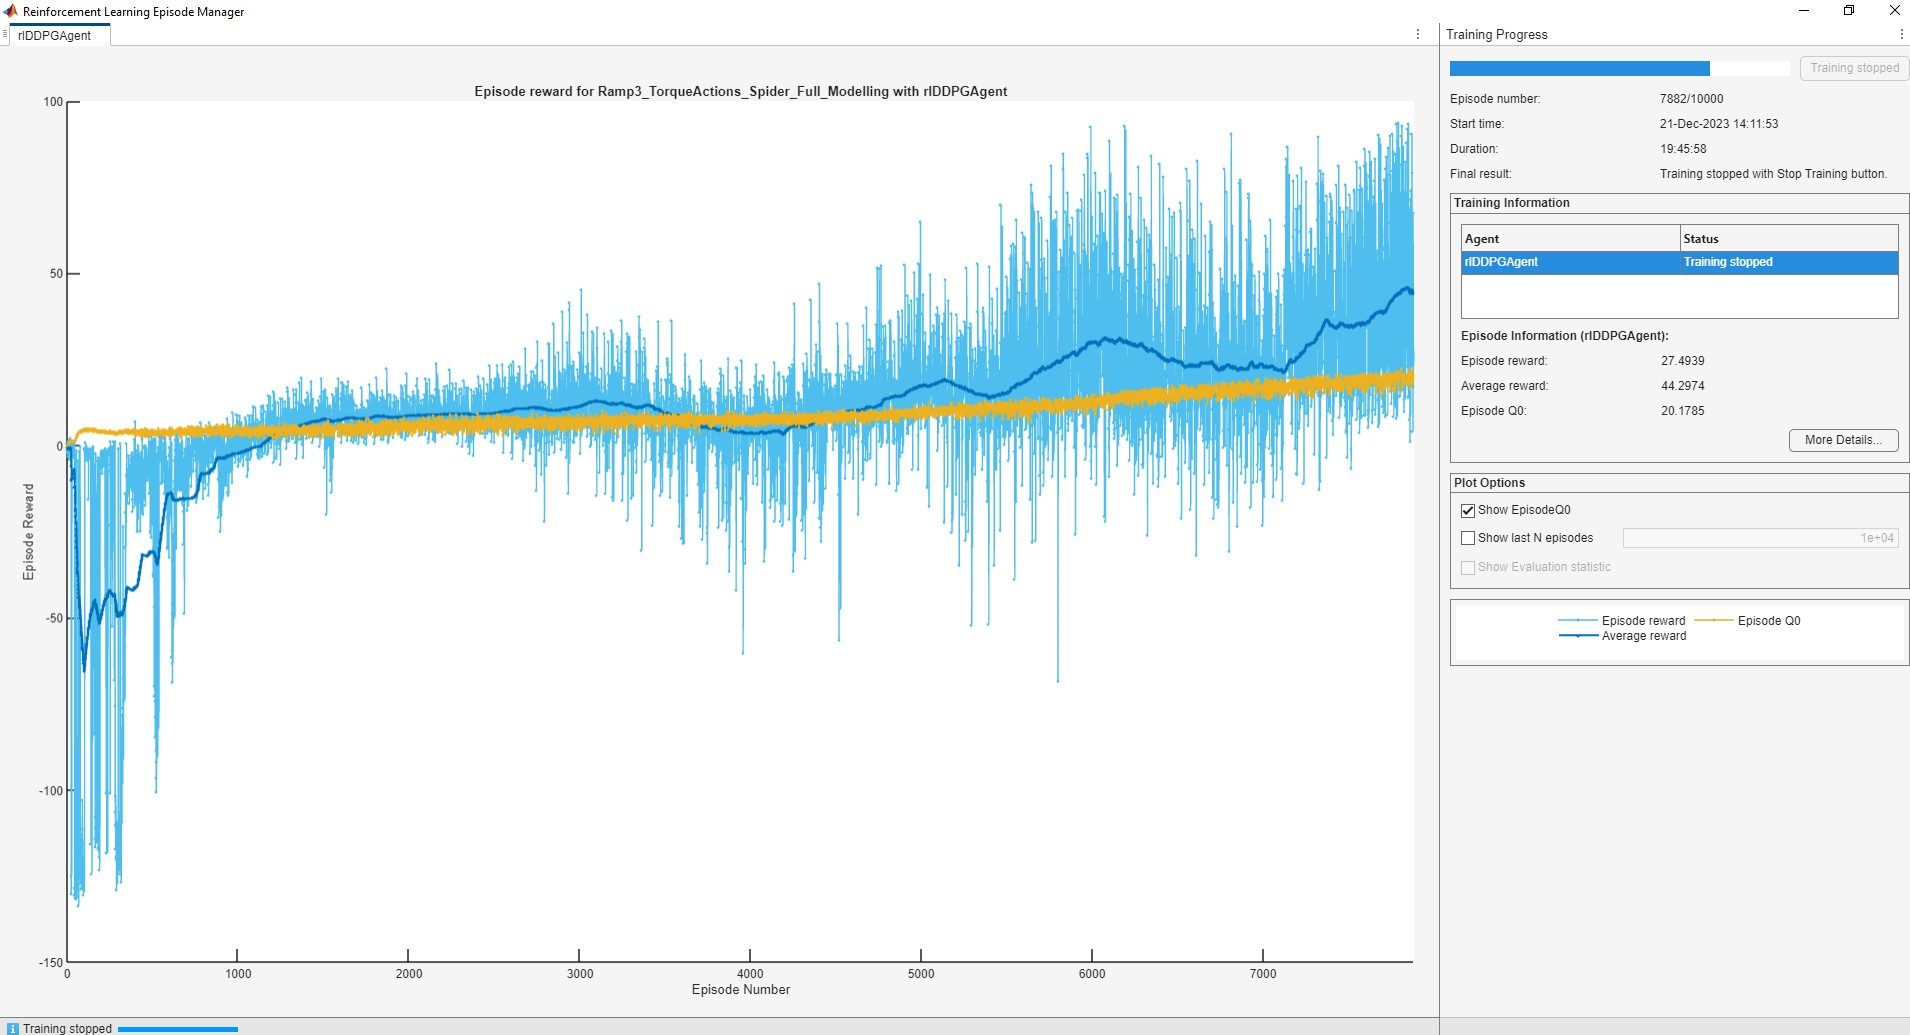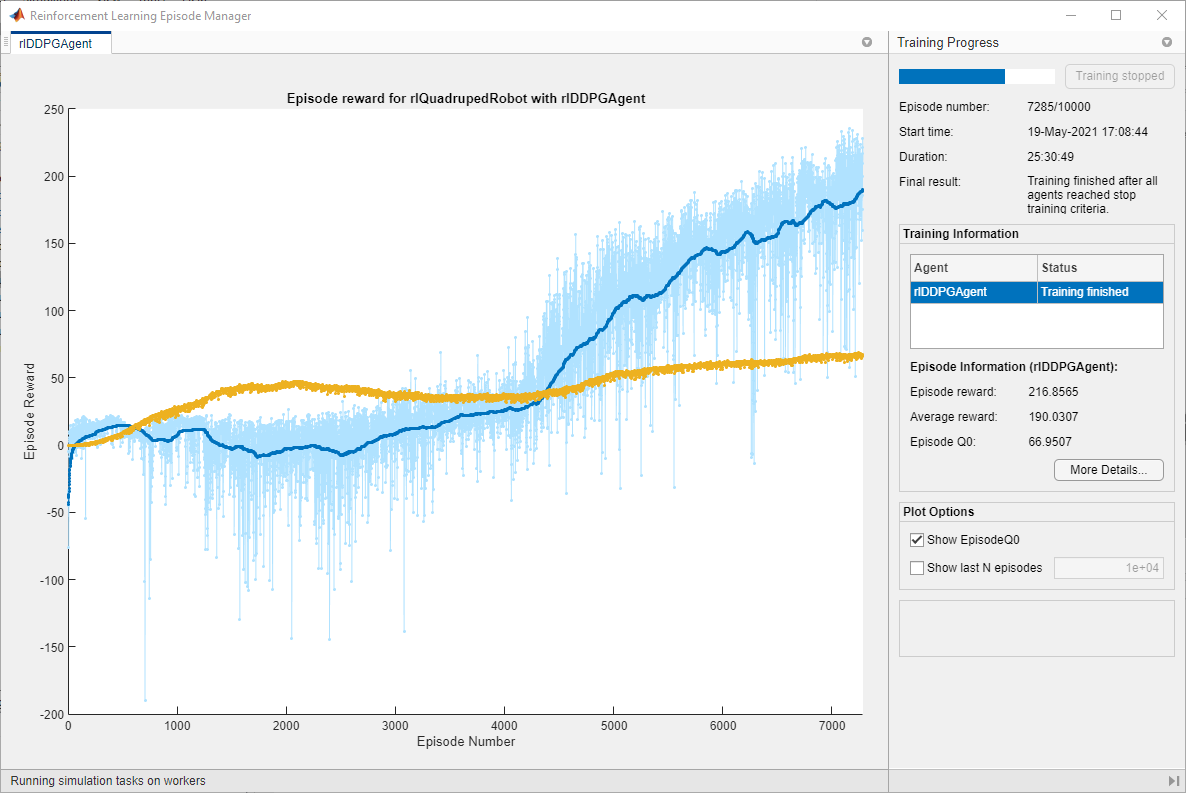

## Simulate Trained Agent

Fix the random generator seed for reproducibility.

rng(0)

To validate the performance of the trained agent, simulate it within the robot environment. For more information on agent simulation, see [`rlSimulationOptions`](docid:rl_ref#mw_983bb2e9-0115-4548-8daa-687037e090b2) and [`sim`](docid:rl_ref#mw_e6296379-23b5-4819-a13b-210681e153bf).

simOptions = rlSimulationOptions('MaxSteps',maxSteps);
experience = sim(env,agent,simOptions);

# Saved Agent Simulation

To run the simulation using the saved agents files that are in the savedAgents folder. Extract the saved Agents compressed file and load one of the saved agents.

SpiderParameters;
load('Agent1.mat','saved_agent');
agent = saved_agent;

Zaid H. Jaber <z.h.jaber@outlook.com>

Princess Sumaya University for Technology

Available online: [https://github.com/ZaidHJaber/Four-legged-Spider-Robot-RL-locomotion.git](https://github.com/ZaidHJaber/Four-legged-Spider-Robot-RL-locomotion.git)

2024